# Example: Unicycle Car model

The code below gives a reachability analysis example for neural network control systems in CORA.

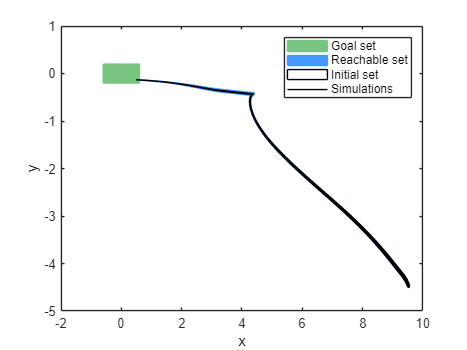

% Parameters --------------------------------------------------------------

params = struct();
params.tFinal = 10;
params.R0 = polyZonotope(interval([9.5; -4.5; 2.1; 1.5], [9.55; -4.45; 2.11; 1.51]));

% Reachability Settings ---------------------------------------------------

options = struct();
options.timeStep = 0.1;
options.alg = 'lin';
options.tensorOrder = 2;
options.taylorTerms = 4;
options.zonotopeOrder = 100;

% Settings for NN evaluation ----------------------------------------------

options.nn.poly_method = "singh";

% System Dynamics ---------------------------------------------------------

% open-loop system
f = @(x, u) [x(4) * cos(x(3)); x(4) * sin(x(3)); u(2) - 20; u(1) - 20 + u(3)];
sys = nonlinearSys(f);

% load neural network controller
% [4, 500, 2]
load('controllerUnicycle.mat');
nn = neuralNetwork({ ...
    nnLinearLayer(W{1}, b{1}), ...
    nnReLULayer(), ...
    nnLinearLayer(W{2}, b{2}), ...
    nnReLULayer(), ...
});

% construct neural network controlled system
sys = neurNetContrSys(sys, nn, 0.2);

% Specification -----------------------------------------------------------

goalSet = interval(-[0.6; 0.2; 0.06; 0.3], [0.6; 0.2; 0.06; 0.3]);
spec = specification(goalSet, 'safeSet', interval(params.tFinal));

% Verification ------------------------------------------------------------

[res, R, simRes] = verify(sys, spec, params, options, false);

% Visualization -----------------------------------------------------------

figure; hold on; box on;

% plot goal set
plot(specification(goalSet, 'safeSet'), [1, 2], 'DisplayName', 'Goal set');

% plot reachable set
useCORAcolors("CORA:contDynamics")
plot(R, [1, 2], 'DisplayName', 'Reachable set');

% plot initial set
plot(R(1).R0, [1, 2], 'DisplayName', 'Initial set');

% plot simulations
plot(simRes,[1, 2], 'DisplayName', 'Simulations');

% labels and legend
xlabel('x'); ylabel('y');
legend()